clear

% Initialization

x0 = [0;0;deg2rad(0);0;0;0];
u0 = [0;0];

% x0 = [500;500;deg2rad(90);50;0;0];
% u0 = [0;0];


% Pridiction Horizon

Ts = 0.0625;
pPlanner = 160;

planner = nlmpcMultistage(pPlanner,6,2);
planner.Ts = Ts;

planner.Model.StateFcn = 'VehicleStateFcn';
planner.Model.StateJacFcn = 'VehicleStateJacobianFcn';

% Constraints

planner.MV(1).Min = 0;
planner.MV(1).Max = 5000;
planner.MV(2).Min = deg2rad(-40);
planner.MV(2).Max = deg2rad(40);

planner.States(2).Min = 0;

for ct=1:pPlanner
    planner.Stages(ct).CostFcn = 'VehiclePlannerCostFcn';
    planner.Stages(ct).CostJacFcn = 'VehiclePlannerCostGradientFcn';
end

planner.Stages(40).EqConFcn = 'VehiclePlannerEqConFunction';
planner.Stages(80).EqConFcn = 'VehiclePlannerEqConFunction2';
planner.Stages(120).EqConFcn = 'VehiclePlannerEqConFunction3';

% planner.Model.TerminalState = [500;500;deg2rad(90);25;0;0];
planner.Model.TerminalState = [300;0;deg2rad(0);0;0;0];

planner.Optimization.SolverOptions.MaxIterations = 1000;

% Compute Optimal Path

fprintf('Vehicle planner running...\n');

Vehicle planner running...


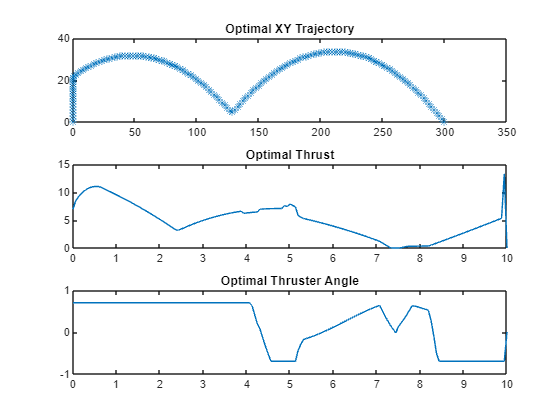

tic;
[~,~,info] = nlmpcmove(planner,x0,u0);
t=toc;

% Plot

figure
subplot(3,1,1)
plot(info.Xopt(:,1),info.Xopt(:,2),'*')
title('Optimal XY Trajectory')
subplot(3,1,2)
plot(info.Topt,info.MVopt(:,1))
title('Optimal Thrust')
subplot(3,1,3)
plot(info.Topt,info.MVopt(:,2))
title('Optimal Thruster Angle')




xpos = [info.Topt info.Xopt(:,1)];
ypos = [info.Topt info.Xopt(:,2)];
zpos = [info.Topt zeros(161,1)];
tangle = [info.Topt info.Xopt(:,3)];
angle = [info.Topt zeros(161,1)];

xvel = [info.Topt info.Xopt(:,4)];
yvel = [info.Topt info.Xopt(:,5)];